### Find videos and results by Number of test:

mainFolderPath = strcat('C:\Users\M.Vulf\Desktop\_Generating droplets\');
videoFolderPath = strcat(mainFolderPath, 'VIDEO_DATA\CROPPED_VIDEO\');
imgProcessingResFolderPath = strcat(mainFolderPath, 'IMAGE_PROCESSING_DATA\');
% cropping folder
croppingFolderPath = strcat(mainFolderPath, "VIDEO_DATA\cropping_data\");
% data path
%cropDataName = "cropping_video.csv";
%cropDataPath = strcat(croppingFolderPath, cropDataName);

procDataName = "image_processing.csv";
procDataPath = strcat(imgProcessingResFolderPath, procDataName);

strTestNum = "0519";
testNum = uint16(str2double(strTestNum));

% CREATE VIDEO TABLE
videoT = struct2table(dir(strcat(videoFolderPath,strTestNum,'_photron_*.avi')));
videoCount = height(videoT);
disp(strcat("Test #", strTestNum));

Test #0519


disp(strcat("Count of videos: ", string(videoCount)));

Count of videos: 2


% LOAD IMAGE PROCESSING TABLE
imgprocT = readtable(procDataPath);

 

#### Load results

numRange =1

numRange = 1


toShow = (imgprocT.test == testNum)&(imgprocT.crop == numRange);
lastRes = imgprocT(toShow,:);
if height(lastRes)>0
    disp("Current values:")
    lastRes = imgprocT(toShow,:);
    disp(lastRes);
else
    disp("NO values")
end

Current values:


    test    crop    autoFlowType    autoDropCount    pixDiameter    sigmaPixDiameter    startingPixVelocity    endingPixVelocity
    ____    ____    ____________    _____________    ___________    ________________    ___________________    _________________

    519      1       {'Single'}           1            81.649            1.0037                7.121                31.116      



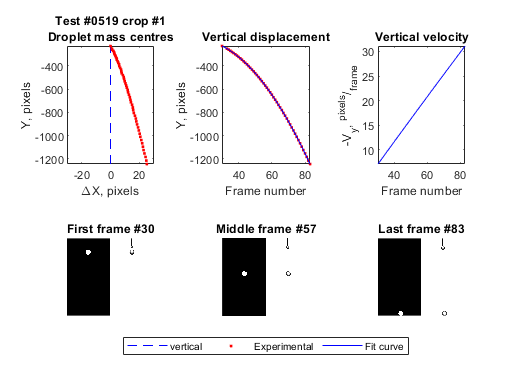


figName = strcat(strTestNum,"_imgproc_", string(numRange), ".fig");
figPath = strcat(imgProcessingResFolderPath, figName);

if exist(figPath,"file")
    figure(openfig(figPath))
else
    disp("Error! No such file.")
end

### Get videos

#### load template & videos from disk

 
% LOAD Template
templateName = strcat(strTestNum,"_template.jpg");
templatePath = strcat(croppingFolderPath, templateName);
if exist(templatePath,'file')    
    templateOneTest = imread(templatePath);
    disp(strcat(templateName," loaded"));
else
    disp("Error! Template image not found.")
end

0241_template.jpg loaded


% LOAD VIDEOS
allVideosOneTest = cell(videoCount,1);
for numRange = 1:videoCount
    if videoCount > 1
        videoPath = string(strcat(videoT.folder(numRange), '\', videoT.name(numRange)));
    else
        videoPath = string(strcat(videoT.folder, '\', videoT.name));
    end
    obj = VideoReader(videoPath);
    disp(strcat(string(numRange), ") loading..."));
    allVideosOneTest{numRange} = obj.read();
    disp("...loaded");
end

1) loading...


...loaded


2) loading...


...loaded


#### Template correction

noizeKoef = 1

noizeKoef = 1

valueQuantile = 0.7

valueQuantile = 0.7000

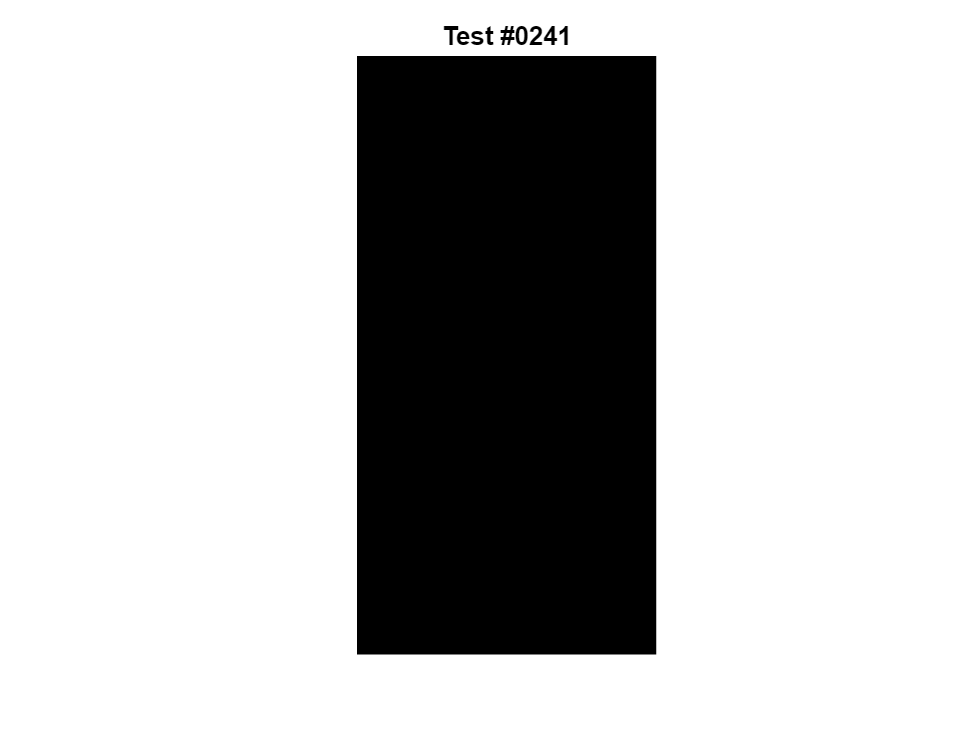

 
%clf;
figure;

newTemplate = correctTemplate(templateOneTest,noizeKoef,strTestNum,valueQuantile);

### **Analyze frames**

**threshold - **grayscale value (1 to 256) for binarizing image (logical 1 if intensity > threshold);

**closeRadius** - disk radius of morphological structuring element for closing areas *(**low value** - droplets with morphological defects, **high value* - combines closing droplets*)*;

**minPixels** - max area of region for deliminating.

numRange =1

numRange = 1

threshold = 50

threshold = 50

closeRadius = 20

closeRadius = 20

minPixels = 30

minPixels = 30

dropletsCountLimit = 4

dropletsCountLimit = 4

needleOnFrame = false

needleOnFrame = logical
   0



 

analyzedFrames = analyzeFrames(allVideosOneTest, newTemplate, ...
    numRange, threshold, closeRadius, minPixels); 

framesCount = length(analyzedFrames);
disp(strcat("Current frames count: ", sprintf("%d",framesCount)));

Current frames count: 97



[estimDropCount, flowType, allDropCount] =...
    getEstimDropCount(analyzedFrames, dropletsCountLimit, needleOnFrame);

Estimated droplets count: 1
Flow type: Single



figTitle = strcat('Test #',strTestNum,' crop #',string(numRange));

#### Show binary and image

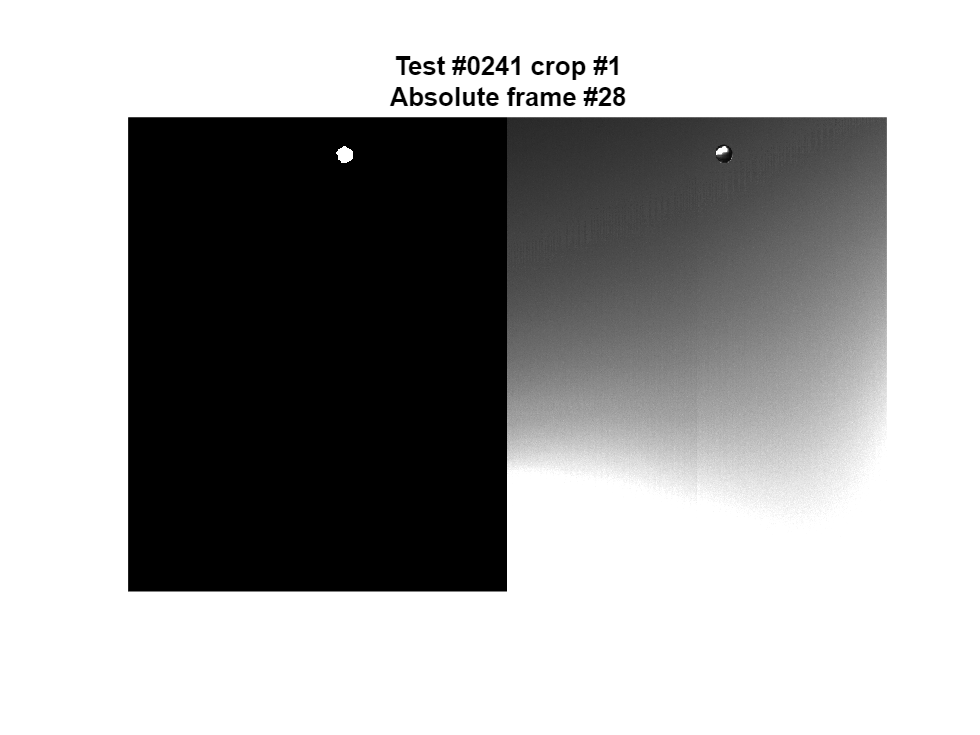

relFrameNum = 28;

% DISPLAY
%clf('reset');
f2 = figure;
t2 = tiledlayout(f2,1,1);
nexttile;
% display current frame
montage({analyzedFrames{relFrameNum}.binImg,...
    analyzedFrames{relFrameNum}.img});
handle = title({figTitle,strcat("Absolute frame #",string(analyzedFrames{relFrameNum}.frameNum))});

#### Change flow type (*if necessary*)

flowFlag = false;
manFlowType = "No";
manDropCount = 1;
if flowFlag
    flowType = manFlowType
    estimDropCount = manDropCount
end
 

### Get droplets characteristics

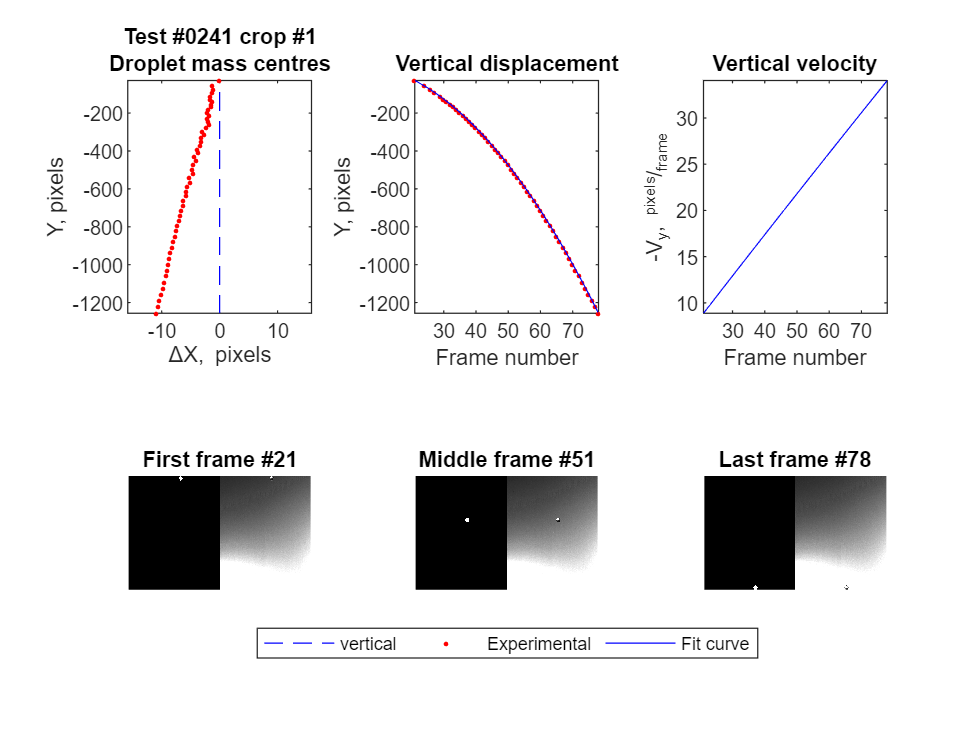

First relative frame number, when droplet exists: 1
Last relative frame number, when droplet exists: 97
Average droplet's diameter, pixels: 48.0
Sigma of droplet's diameter, pixels: 1.5
Starting velocity, pixels per frame: 8.9
Ending velocity, pixels per frame: 34.1


 

f3 = figure;
[propT, dropDiameter, fitYvelocity] = postAnalyzeFrames(analyzedFrames,...
    estimDropCount, f3, figTitle);


if estimDropCount ~= 1
    disp("NOT Single flow type")
end

### Save results

 
if estimDropCount ~= 1 % NOT SINGLE
    disp("NO Figure")
else
    figName = strcat(strTestNum,'_imgproc_',string(numRange));
    fullFigName = strcat(imgProcessingResFolderPath, figName, '.fig');
    savefig(fullFigName);
    disp(strcat(figName, " - saved"));

    % SAVE TABLE-Values
    propTName = strcat(strTestNum,'_pixprop_',string(numRange));
    fullTName = strcat(imgProcessingResFolderPath, propTName, '.csv');
    writetable(propT,fullTName);
    disp(strcat(propTName, " - saved"));
end

0241_imgproc_1 - saved


0241_pixprop_1 - saved



% SAVE VALUES
% IF NOT SINGLE - save only flowType & estimDropCount (others = 0 automatically)
toShow = (imgprocT.test == testNum)&(imgprocT.crop == numRange);
lastRes = imgprocT(toShow,:);
if height(lastRes)>0
    disp("Last values:")
    lastRes = imgprocT(toShow,:);
    disp(lastRes);
else
    disp("NO values before")
end

Last values:


    test    crop    autoFlowType    autoDropCount    pixDiameter    sigmaPixDiameter    startingPixVelocity    endingPixVelocity
    ____    ____    ____________    _____________    ___________    ________________    ___________________    _________________

    241      1       {'Multi'}            2               0                0                     0                     0        




% delete previos ranges
toDelete = toShow;
imgprocT(toDelete,:) = [];

% add new value
savedRow = {testNum,numRange,flowType,estimDropCount,...
    dropDiameter(1),dropDiameter(2),fitYvelocity(1),fitYvelocity(2)};
imgprocT = [imgprocT;savedRow];

% WRITE TABLE
writetable(imgprocT,procDataPath);

disp('Saved row:')

Saved row:


toShow = (imgprocT.test == testNum)&(imgprocT.crop == numRange);
newRes = imgprocT(toShow,:);
disp(newRes);

    test    crop    autoFlowType    autoDropCount    pixDiameter    sigmaPixDiameter    startingPixVelocity    endingPixVelocity
    ____    ____    ____________    _____________    ___________    ________________    ___________________    _________________

    241      1        "Single"            1            48.031            1.5337               8.8751                34.059      

